clear

addpath('C:\Users\sebas\Documents\Data\CARACTERIZACION');
plexi = [20 21 22];

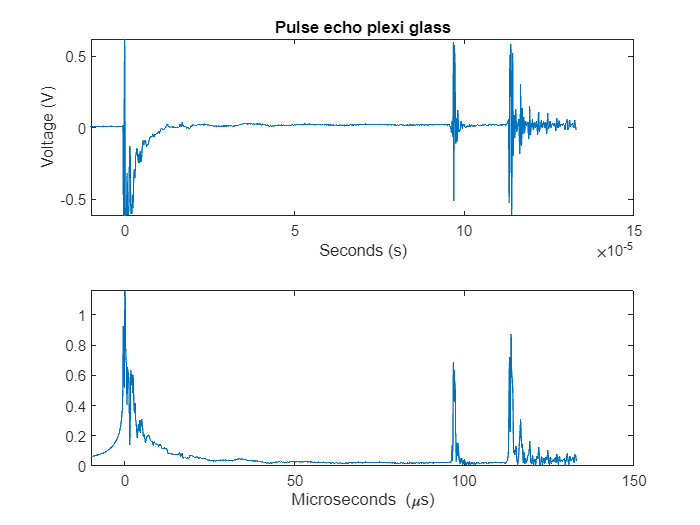

ii = 20;
data_r = readmatrix(sprintf('TEK000%d.CSV', ii),"Range", "A17:B20016");
N = 2000; % # samples recorded
t = data_r(:,1); %[s]
volt = data_r(:,2); %[V]
Fs = 1/((t(end)-t(1))/N); % sampling frequency [samples/s]

envol_ref= hilbert(volt);
figure,
tiledlayout(2,1)
nexttile,
plot (t,volt), xlabel ('Seconds (s)'), ylabel('Voltage (V)'),xlim ([-0.1e-4 1.5e-4]), title ('Pulse echo plexi glass')
nexttile,
plot(t*1e6,abs(envol_ref)), xlim ([-0.1e-4*1e6 1.5e-4*1e6]);
xlabel ('Microseconds (\mus)')

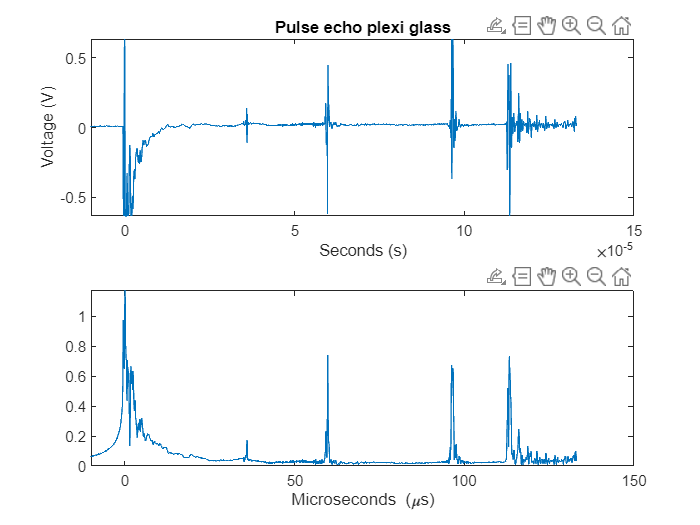

ii = 17;
data_r = readmatrix(sprintf('TEK000%d.CSV', ii),"Range", "A17:B20016");
N = 2000; % # samples recorded
t = data_r(:,1); %[s]
volt = data_r(:,2); %[V]
Fs = 1/((t(end)-t(1))/N); % sampling frequency [samples/s]

envol_ref= hilbert(volt);
figure,
tiledlayout(2,1)
nexttile,
plot (t,volt), xlabel ('Seconds (s)'), ylabel('Voltage (V)'),xlim ([-0.1e-4 1.5e-4]), title ('Pulse echo plexi glass')
nexttile,
plot(t*1e6,abs(envol_ref)), xlim ([-0.1e-4*1e6 1.5e-4*1e6]);
xlabel ('Microseconds (\mus)')

TIEMPOS EN EL PHANTOM DE GELATINA

cWater = 1482.97;
tPlexi = 96.96e-6;
dPlexi = cWater*tPlexi/2

dPlexi = 0.0719

TIEMPOS EN LA ADQUISICION CON EL PHANTOM EN MEDIO

t1 = 36e-6;
t2 = 59.76e-6;
t3 = 96.24e-6;
dWater = cWater*t1/2 + cWater*(t3-t2)/2

dWater = 0.0537

dPhantom = dPlexi - dWater

dPhantom = 0.0182

cPhantom = dPhantom/(t2-t1)*2

cPhantom = 1.5279e+03

# Nuevo phantom

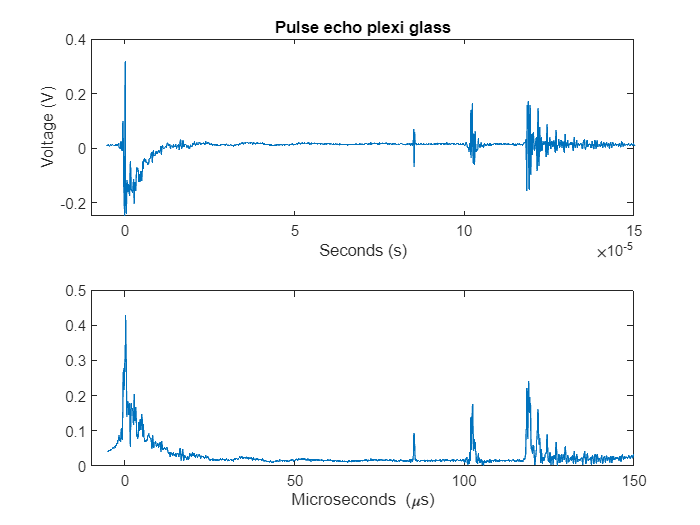

clear

addpath('C:\Users\sebas\Documents\Data\CARACTERIZACION');

ii = 36;
data_r = readmatrix(sprintf('TEK000%d.CSV', ii),"Range", "A17:B20016");
N = 2000; % # samples recorded
t = data_r(:,1); %[s]
volt = data_r(:,2); %[V]
Fs = 1/((t(end)-t(1))/N); % sampling frequency [samples/s]

envol_ref= hilbert(volt);
figure,
tiledlayout(2,1)
nexttile,
plot (t,volt), xlabel ('Seconds (s)'), ylabel('Voltage (V)'),xlim ([-0.1e-4 1.5e-4]), title ('Pulse echo plexi glass')
nexttile,
plot(t*1e6,abs(envol_ref)), xlim ([-0.1e-4*1e6 1.5e-4*1e6]);
xlabel ('Microseconds (\mus)')

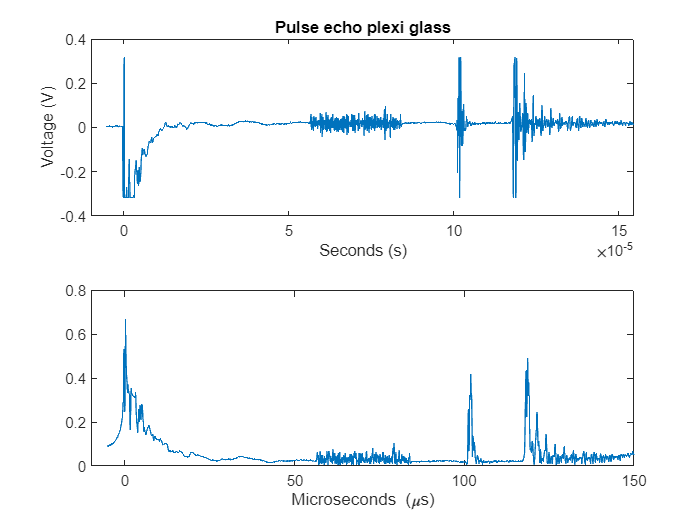

ii = 33;
data_r = readmatrix(sprintf('TEK000%d.CSV', ii),"Range", "A17:B20016");
N = 2000; % # samples recorded
t = data_r(:,1); %[s]
volt = data_r(:,2); %[V]
Fs = 1/((t(end)-t(1))/N); % sampling frequency [samples/s]

envol_ref= hilbert(volt);
figure,
tiledlayout(2,1)
nexttile,
plot (t,volt), xlabel ('Seconds (s)'), ylabel('Voltage (V)'),xlim ([-0.1e-4 1.5e-4]), title ('Pulse echo plexi glass')
nexttile,
plot(t*1e6,abs(envol_ref)), xlim ([-0.1e-4*1e6 1.5e-4*1e6]);
xlabel ('Microseconds (\mus)')

cWater = 1483.275;
tPlexi = 102.4e-6;
dPlexi = cWater*tPlexi/2

dPlexi = 0.0759

t1 = 56.5e-6;
t2 = 84.16e-6;
t3 = 101.92e-6;
dWater = cWater*t1/2 + cWater*(t3-t2)/2

dWater = 0.0551

dPhantom = dPlexi - dWater

dPhantom = 0.0209

cPhantom = dPhantom/(t2-t1)*2

cPhantom = 1.5090e+03